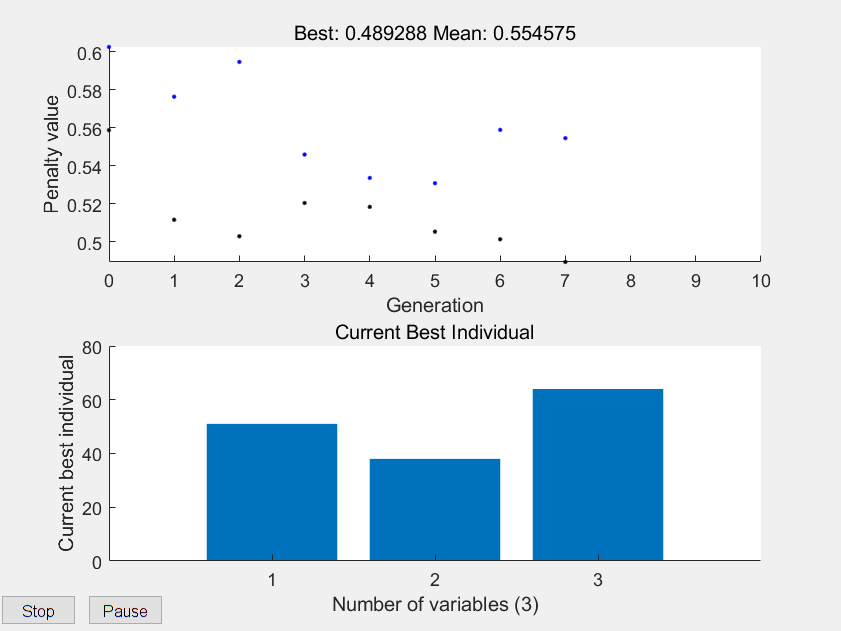

错误使用 trainNetwork
Encountered unexpected error during CUDA execution. The CUDA error was:
CUDA_ERROR_LAUNCH_FAILED

出错 adaptGRU (第 60 行)
    net = trainNetwork(XTrain,YTrain,layers,options);

出错 gaGRU>@(X)adaptGRU(X,inputs,outputs) (第 12 行)
[X,fval

index=3;
IntCon = 1:index; 
% LB=ones(1,22)*-4;
% UB=ones(1,22)*4;
LB=[10,10,10];
UB=[90,90,90];


options = optimoptions('ga','PlotFcn', ["gaplotbestf","gaplotbestindiv"],'UseParallel', true,'PopulationSize', 8,'Generations', 10);                     
% X=1:nVars;
tic
[X,fval] = ga(@(X)adaptGRU(X,inputs,outputs),index,[],[],[],[],LB,UB,[],IntCon, options);

toc